clc;clear;
folder_path = '../Data/M30_0420';
load(folder_path + "/Trail_data.mat");

window_ms =2000;

% 假设的参数
trial_index = 5;       % 选择第一个试次
neuron_index = 1000;      % 选择第一个神经元
t_stimulus = round(window_ms / 250); % 刺激出现的时间点
stim_duration = 16;    % 假设刺激持续16个时间点

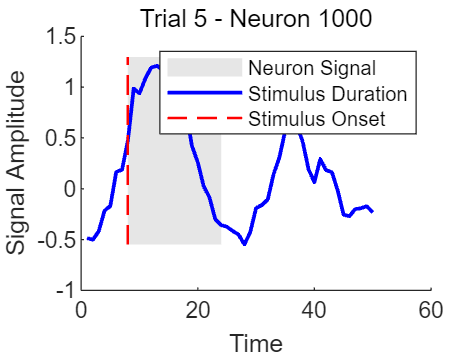

% 提取单个试次的神经元信号
neuron_signal = trails{trial_index, neuron_index};  % l x 1 数组

% 时间向量
time = 1:length(neuron_signal);

% 绘制神经元信号
figure;

hold on;

% 绘制刺激持续时间的背景
stim_start = t_stimulus;
stim_end = t_stimulus + stim_duration;

% 使用 patch 函数创建浅灰色背景
patch([stim_start stim_end stim_end stim_start], ...
      [min(neuron_signal) min(neuron_signal) max(neuron_signal) max(neuron_signal)], ...
      [0.9 0.9 0.9], 'EdgeColor', 'none');

plot(time, neuron_signal, 'b', 'LineWidth', 1.5);

% 在图上标示刺激出现时间
plot([t_stimulus t_stimulus], [min(neuron_signal) max(neuron_signal)], 'r--', 'LineWidth', 1);

% 添加标题和标签
title(['Trial ', num2str(trial_index), ' - Neuron ', num2str(neuron_index)]);
xlabel('Time');
ylabel('Signal Amplitude');

% 显示图例
legend('Neuron Signal', 'Stimulus Duration', 'Stimulus Onset');

% 关闭保持绘图
hold off;

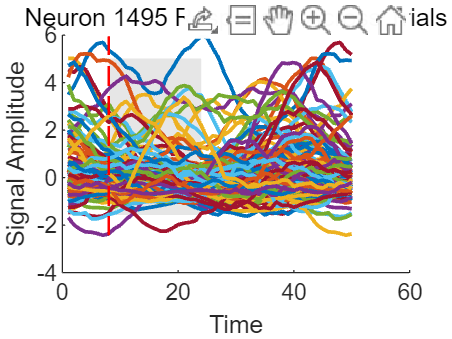

% 假设的参数
neuron_index = 1495; 
num_trials = size(trails, 1); % 试次数量

% 创建图形窗口
figure;

% 绘制每个试次的神经元信号
hold on; % 保持绘图

% 使用 patch 函数创建浅灰色背景，背景的高度覆盖所有信号的范围
patch([stim_start stim_end stim_end stim_start], ...
      [min(y_limits(:)) min(y_limits(:)) max(y_limits(:)) max(y_limits(:))], ...
      [0.9 0.9 0.9], 'EdgeColor', 'none', 'DisplayName', 'Stimulus Duration');
% 绘制刺激持续时间的背景
stim_start = t_stimulus;
stim_end = t_stimulus + stim_duration;
y_limits = []; % 用于存储所有信号的全局y轴范围

for trial_index = 1:num_trials
    % 提取单个试次的神经元信号
    neuron_signal = trails{trial_index, neuron_index}; % l x 1 数组
    time = 1:length(neuron_signal); % 时间向量

    % 绘制神经元信号
    plot(time, neuron_signal, 'LineWidth', 1.5, 'DisplayName', ['Trial ', num2str(trial_index)]);

    % 更新y轴范围
    y_limits = [y_limits; neuron_signal];
end



% 在图上标示刺激出现时间
plot([t_stimulus t_stimulus], [min(y_limits(:)) max(y_limits(:))], 'r--', 'LineWidth', 1, 'DisplayName', 'Stimulus Onset');

% 添加标题和标签
title(['Neuron ', num2str(neuron_index), ' Responses Across Trials']);
xlabel('Time');
ylabel('Signal Amplitude');

% 显示图例
% legend('show');

% 关闭保持绘图
hold off;